# Rock vs No Rock: Data recording sheet

Author: Ross Wilkinson

University: University of Colorado Boulder

## Testing information

- Experiment: Rock vs No Rock

- Objective: Test effect of bicycle lean on maximal power output 

- Date: September 10, 2020

- Location: Locomotion Laboratory

- Subject: BC

- Quarq calibration factor: 329

## Experimental setup

### Protocol reminders

- Charge Garmin, iPad, and IMUs

- Clarify participant understanding and answer questions

- Set saddle height and handlebar position

- Sanitize bicycle

- Calibrate power meter

- Setup cooling fan

- Gift card and signature

### Experimental conditions

- Preferred Lean

- Self-restricted

- Locked

### Trial order

- Warm up: 5 min at ~100 W (3.5 lb)

- Familiarization: Standing and leaning (8.5 lb)

- Pmax Test: 3 x hanging weights under condition 1

- Block 1: Randomize

- Block 2: Randomize

- Block 3: Randomize

### Environmental conditions

- Temperature (C): 21.1

- Humidity (%):  33.7      

- Pressure (mmHg): 636           

- Altitude (m): 1641

### Subject characteristics

- Sex: M

- Age (yrs): 21

- Mass (lb / kg): 145 / 66

- Height (ft / m): 6'2" / 1.88

## Results

Use mass to calculate individualised hanging weights for Pmax Test.

mass = 145;
listPerc = [0.06; 0.12; 0.18];
listHang = listPerc * mass

### Pmax test

Record Pmax test results. Fit curve to predict optimal hanging weight.

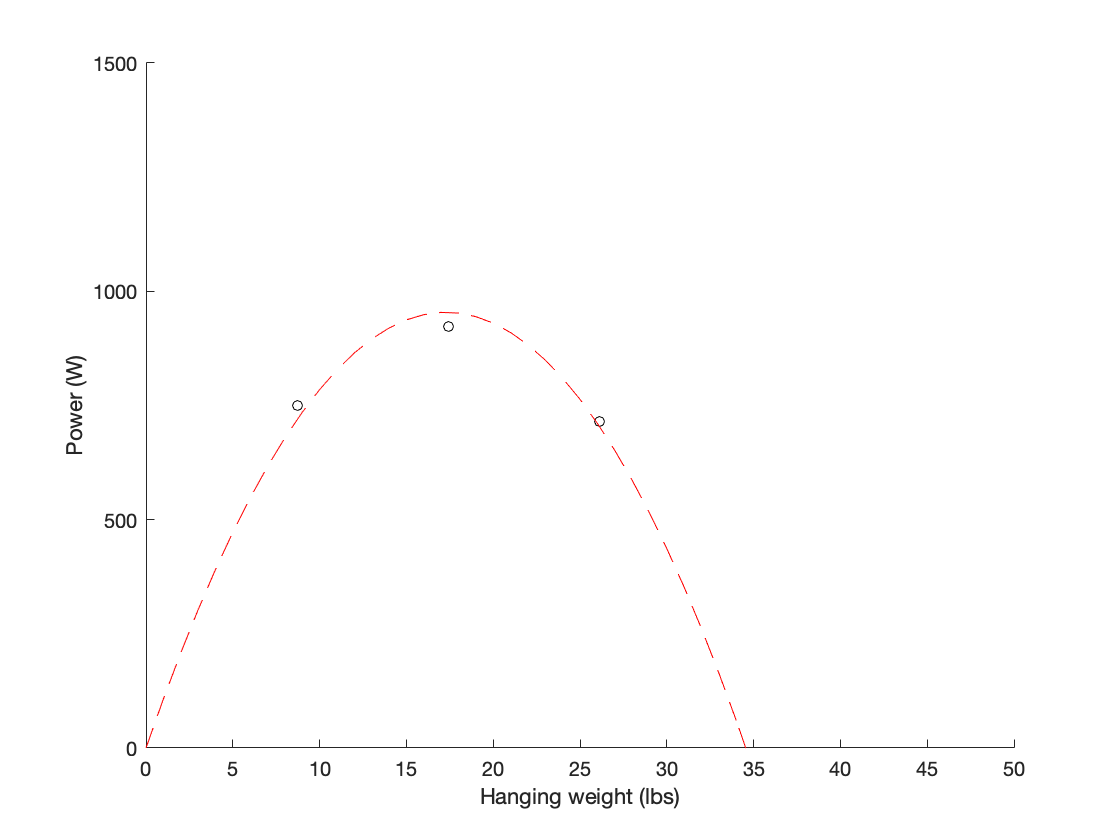

x = listHang; % hanging weight
y = [751; 922; 716]; % power output

% fit curve
[c, ~, ~] = fit(x,y,'poly2','Lower',[-Inf -Inf 0],'Upper',[Inf Inf 0]);

new_x = 0:50;
new_y = c.p1*new_x.^2+c.p2*new_x+c.p3;

% plot curve
scatter(x,y,25,'k');
hold on
plot(new_x,new_y,'r--')

% edit figure
box off
xlabel('Hanging weight (lbs)')
ylabel('Power (W)')
xlim([0 50])
ylim([0 1500])


% find optimal x and y
[yOpt,I] = max(new_y);
xOpt = new_x(I);

fprintf('Predicted maximal power output = %4.2f Watts \n', yOpt)

Predicted maximal power output = 953.85 Watts 


fprintf('Predicted optimal hanging weight = %4.2f Lbs \n', xOpt)

Predicted optimal hanging weight = 17.00 Lbs 


### Randomize trial order within each block

randperm(3)

ans =      1     2     3


randperm(3)

ans =      1     3     2


randperm(3)

ans =      2     3     1


### Experimental results

Record results to array then convert to table.

data = [
    9,1,1,17,897,108;
    9,3,1,17,909,109;
    9,2,1,17,870,105;
    9,2,2,17,824,110;
    9,3,2,17,948,114;
    9,1,2,17,937,119;
    9,1,3,17,923,115;
    9,2,3,17,932,116;
    9,3,3,17,969,115;
    ];

T = array2table(data, ...
    'VariableNames',{'subject','condition','trial','hangingWeight','power','cadence'})

T = 9×6 table
    subject    condition    trial    hangingWeight    power    cadence
    _______    _________    _____    _____________    _____    _______

       9           1          1           17           897       108  
       9           3          1           17           909       109  
       9           2          1           17           870       105  
       9           2          2           17           824       110  
       9           3          2           17           948       114  
       9           1          2           17           937       119  
       9           1          3           17           923       115  
       9           2          3           17           932       116  
       9           3          3           17           969       115  


## Data analysis

Calculate mean and SD power and cadence for experimental trials.

varfun(@mean,T,'InputVariables',{'power','cadence'}, ...

ans = 3×4 table
    condition    GroupCount    mean_power    mean_cadence
    _________    __________    __________    ____________

        1            3              919            114   
        2            3           875.33         110.33   
        3            3              942         112.67   


    'GroupingVariables',{'condition'})
varfun(@std,T,'InputVariables',{'power','cadence'}, ...
    'GroupingVariables',{'condition'})

ans = 3×4 table
    condition    GroupCount    std_power    std_cadence
    _________    __________    _________    ___________

        1            3          20.298        5.5678   
        2            3          54.197        5.5076   
        3            3          30.447        3.2146   
